This script produces an average spectrogram based upon several pre-chosen transects for burned basin data from the Chiricahua Mtns. (Delong et al. 2018). The averaging is done using the a Root Mean Square Average. A spectrograms script originally prepared by D. Roth for the class GEGN 598 Point Cloud Data Analysis (CSM, Spring 2020) provided the outline for this code.

clc,clf,clear

%--- Import Data
% Prior to import, point data should be trimmed using SOR filter,
% Rotated so the main channel network is oriented parallel to the y axis,
% and rasterized (output as an Esri ASCII raster, .asc format).

% Currently this code only processes one raster at a time. To switch
% between the two datasets here, uncomment the relevant one and comment out
% the other
info = georasterinfo("chiri_20110611ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc")

info =   RasterInfo with properties:

                Filename: "/Users/danicaroth/Google Drive/Academic/Analysis/Scripts/Spectral_Scripts/Data/chiri_20110611ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc"
        FileModifiedDate: 24-Jul-2020 10:45:30
                FileSize: 47436286
              FileFormat: "Esri ASCII Grid"
              RasterSize: [2936 2164]
                NumBands: 1
            NativeFormat: "single"
    MissingDataIndicator: -9999
              Categories: []
               ColorType: "unknown"
                Colormap: []
         RasterReference: [1×1 map.rasterref.MapCellsReference]
                Metadata: []


[z1,R] = readgeoraster("chiri_20110611ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc");

%info = georasterinfo("chiri_20120314ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc")
%[z1,R] = readgeoraster("chiri_20120314ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc");


%--- Check for mising data in the input raster
m = info.MissingDataIndicator;
ismember(m,z1); %Check for missing data. Answer of 1 means there are cells with no data
%z1 = standardizeMissing(z1,m);
z1t = z1;
log = logical(z1 == m);
z1(log) = NaN; % Set missing data as a NaN
% add in more imports here

% Detrend data (remove lower frequency topography) using a planar detrend
% while omitting NaN values
z1o = z1;
z1 = detrend(z1o,'omitnan'); %Planar detrending step. I will be looking at detrending with a hyperbolic fit, rather than a polynomial

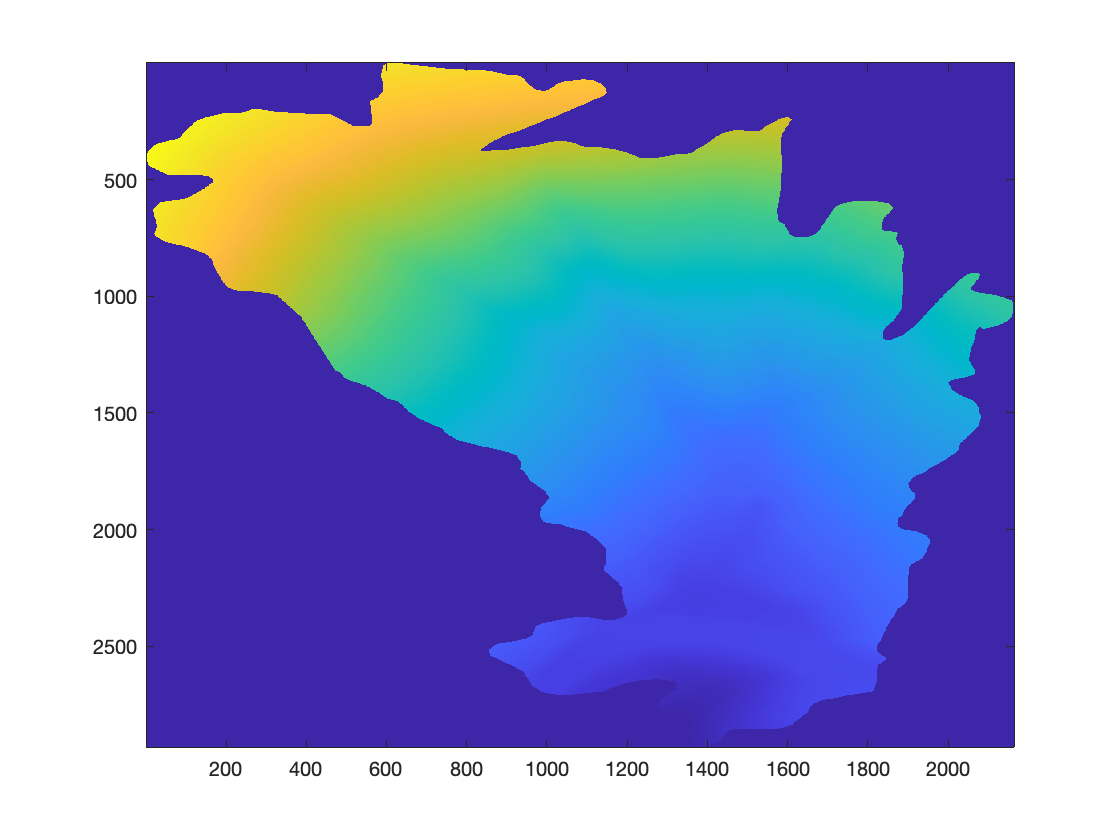

plane1 = z1o - z1;

% Preview gridded data
%clims1 = [2400,max(max(z1))];
figure(1), imagesc(z1o)

%caxis([2450,2650])


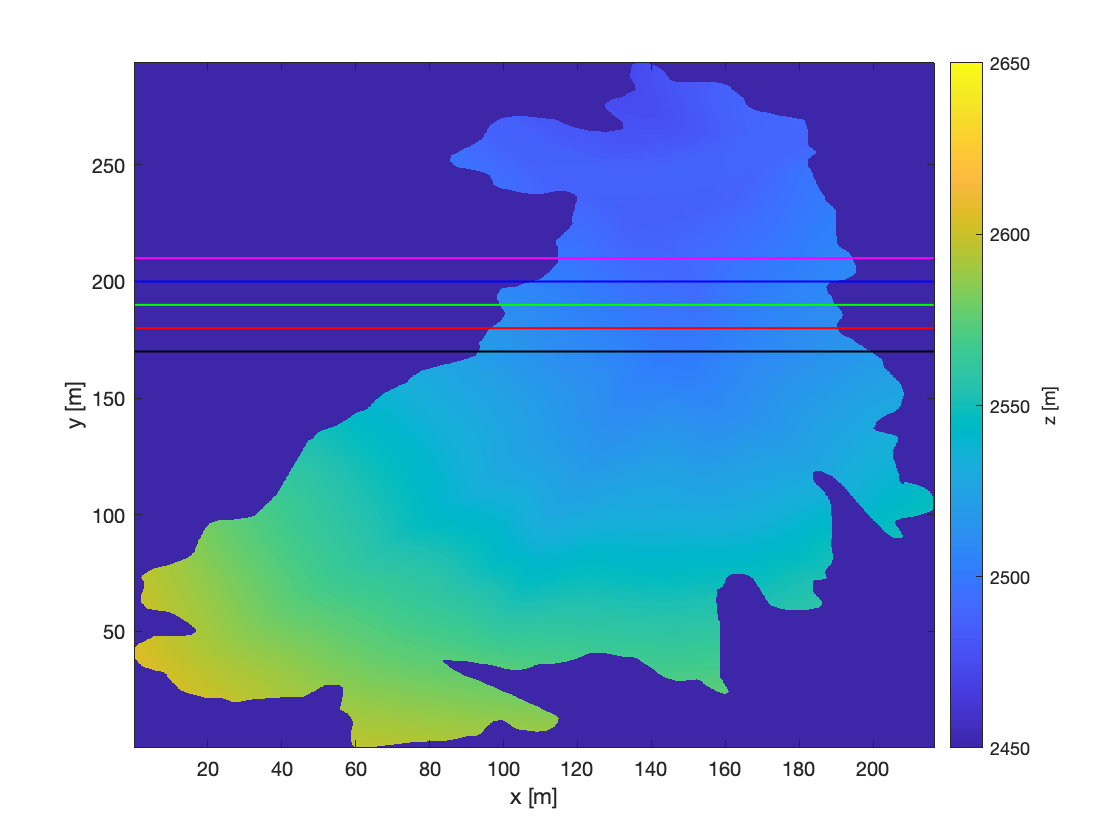

%--- Set additional Parameters
% x and y spacing set using s=sqrt(A/n) for the coarsest cloud
dx = 0.1; % should be set equal to whatever grid spacing we have for the input raster
dy = 0.1;
XX = [1:size(z1,2)];%.*dx; % I'm honestly not sure if this step is essential i.e. rather than using the x and y defined by the raster (it has that right?)*[D: Nope, examine your raster...it's just an N x M matrix of z values]
YY = [1:size(z1,1)];%.*dy;

%--- Plot raw elevation in xy space with transects
figure(2),imagesc(XX,YY,z1o);
axis xy;
xlabel('x [m]');
ylabel('y [m]');
c = colorbar;
caxis([2450,2650])
set(get(c,'label'),'string','z [m]','Rotation',90);

% Set transects (starting with an arbitrary number of 5) 
Ytransect1 = 170; % transect positions in meters from the x axis
Ytransect2 = 180;
Ytransect3 = 190;
Ytransect4 = 200;
Ytransect5 = 210;

Ytrnsctnum1 = round(Ytransect1/dx); %element number for chosen transect based on cell spacing
Ytrnsctnum2 = round(Ytransect2/dx);
Ytrnsctnum3 = round(Ytransect3/dx);
Ytrnsctnum4 = round(Ytransect4/dx);
Ytrnsctnum5 = round(Ytransect5/dx);

figure(2), hold on
plot([XX(1), XX(end)],[YY(Ytrnsctnum1), YY(Ytrnsctnum1)],'k','linewidth',1); %plot a line showing the selected transect 
plot([XX(1), XX(end)],[YY(Ytrnsctnum2), YY(Ytrnsctnum2)],'r','linewidth',1);
plot([XX(1), XX(end)],[YY(Ytrnsctnum3), YY(Ytrnsctnum3)],'g','linewidth',1);
plot([XX(1), XX(end)],[YY(Ytrnsctnum4), YY(Ytrnsctnum4)],'b','linewidth',1);
plot([XX(1), XX(end)],[YY(Ytrnsctnum5), YY(Ytrnsctnum5)],'m','linewidth',1);
hold off

%--- extract z values for the transects from the detrended dataset
ztr1 = z1(Ytrnsctnum1,:); %since we don't with nulls outside the convex shell, just using the raw (not detrended data) for now
ztr2 = z1(Ytrnsctnum2,:); 
ztr3 = z1(Ytrnsctnum3,:); 
ztr4 = z1(Ytrnsctnum4,:); 
ztr5 = z1(Ytrnsctnum5,:); 

% %--- Remove NaNs from transects (This step is required to get the
% %spectrogram function to work on these transects
% log_z1 = isnan(ztr1);
% log_z2 = isnan(ztr2);
% log_z3 = isnan(ztr3);
% log_z4 = isnan(ztr4);
% log_z5 = isnan(ztr5);
% 
% ztr1(log_z1) = []; % Find NaNs and make those cells empty
% ztr2(log_z2) = [];
% ztr3(log_z3) = [];
% ztr4(log_z4) = [];
% ztr5(log_z5) = [];

xb_ztr1 = XX; %create x vectors for z transects
xb_ztr2 = XX;
xb_ztr3 = XX;
xb_ztr4 = XX;
xb_ztr5 = XX;

% xb_ztr1(log_z1) = []; % Adjust lengths of X vectors
% xb_ztr2(log_z2) = [];
% xb_ztr3(log_z3) = [];
% xb_ztr4(log_z4) = [];
% xb_ztr5(log_z5) = [];

%--- Set spatial sampling frequency using sliders
clf

fs = 1/dx; %units of samples/meter
  
window = 30; % window size in points %Should this range be larger?
poverlap = 90; % percent overlap of windows
poverlap = poverlap/100;

%--- Compute Spectrogram parameters for all transects
% Output short-time fourier transform (S), frequency (F), position (X), and 
% PSD (P) arrays from spectrogram function
[S1,F1,X1,P1] = spectrogram(ztr1,window,window*poverlap,window,fs); %note this will not plot

Error using pwelch
Expected x to be finite.

Error in welchparse>parse_inputs (line 94)
validateattributes(x2,{'single','double'}, {'finite','nonnan'},'pwelch','x')

Error in welchparse (line 31)
    parse_inputs(x1,esttype,varargin{:});

Error in

[S2,F2,X2,P2] = spectrogram(ztr2,window,window*poverlap,window,fs);
[S3,F3,X3,P3] = spectrogram(ztr3,window,window*poverlap,window,fs);
[S4,F4,X4,P4] = spectrogram(ztr4,window,window*poverlap,window,fs);
[S5,F5,X5,P5] = spectrogram(ztr5,window,window*poverlap,window,fs);

%--- Compute average P (spectral power) using Root Mean Square averaging
%(square root of average of squares)
clear all_P
clear all_P2

% Pad smaller 4 P arrays with zeros to allow for averaging (function "padding.m" written to check length and apply padding if necessary)
max_dim = max([size(P1,2) size(P2,2) size(P3,2) size(P4,2) size(P5,2)]);
P1p = padding(P1,max_dim);
P2p = padding(P2,max_dim);
P3p = padding(P3,max_dim);
P4p = padding(P4,max_dim);
P5p = padding(P5,max_dim);

all_P(:,:,1) = P1p.^2; %Combine P arrays from each spectrogram and square each element
all_P(:,:,2) = P2p.^2; 
all_P(:,:,3) = P3p.^2;
all_P(:,:,4) = P4p.^2;
all_P(:,:,5) = P5p.^2;
mean_all_P = mean(all_P,3); %compute mean of squares
RMSavg_P = sqrt(mean_all_P); %take square root to get RMS average

%compute normal arithmetic average, rather than root mean square for
%comparison
all_P2(:,:,1) = P1p; 
all_P2(:,:,2) = P2p; 
all_P2(:,:,3) = P3p;
all_P2(:,:,4) = P4p;
all_P2(:,:,5) = P5p;
mean_all_P2 = mean(all_P,3); %compute mean


%--- Plot averaged spectra with line plots of all transects
figure(4)
subplot(4,1,1) %plot all transects with true z values
plot(XX,z1o(Ytrnsctnum1,:),'k')
hold on
plot(XX,z1o(Ytrnsctnum2,:),'r')
plot(XX,z1o(Ytrnsctnum3,:),'g')
plot(XX,z1o(Ytrnsctnum4,:),'b')
plot(XX,z1o(Ytrnsctnum5,:),'m')
xlabel('horizontal distance [m]')
ylabel('Original z [m]')
legend(['Trnsct 1'; 'Trnsct 2'; 'Trnsct 3'; 'Trnsct 4'; 'Trnsct 5' ],'location','eastoutside')
xlimits2=get(gca,'xlim');
hold off

subplot(4,1,2) %plot all transects with detrended z values
plot(XX,z1(Ytrnsctnum1,:),'k')
hold on
plot(XX,z1(Ytrnsctnum2,:),'r')
plot(XX,z1(Ytrnsctnum3,:),'g')
plot(XX,z1(Ytrnsctnum4,:),'b')
plot(XX,z1(Ytrnsctnum5,:),'m')
xlabel('horizontal distance [m]')
ylabel('Detrended z [m]')
xlim(xlimits2)
hold off

figure(5)
for i=1:5
subplot(5,1,i) %Plot averaged spectrogram
eval(['imagesc(xb_ztr',str2num(i),',F',str2num(i),',10*log10(P',str2num(i),'));']);
end
%Taking the logarithm to account for fact that the spectral power data
%varies log normally over several orders of magnitude.

%imagesc(xb_ztr1,F1,10*log10(abs(mean_all_P2))) %if wanting to take an
%arithmetic mean of spectral power, rather than a Root Mean Square average

set(gca,'YDir','Normal') %adjust plot properties and add labels
xlabel('horizontal distance [m]')
ylabel('frequency [1/m]')
c = colorbar;
%set(get(c,'label'),'string','Power/frequency [dB(1/m)]');
set(get(c,'label'),'string','Log10 Power/frequency [dB(1/m)]'); % for when using the log10 of spectral power
set(c,'location','northoutside')
xlim(xlimits2)